%收益问题
f=[-0.05;-0.27;-0.19;-0.185;-0.185];
a=(0:0.001:0.05)%从0 步长为0.01取到0.05

a =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


%不等式
A=[zeros(4,1),diag([0.025,0.015,0.055,0.026])]%把两个矩阵拼在一起

A =          0    0.0250         0         0         0
         0         0    0.0150         0         0
         0         0         0    0.0550         0
         0         0         0         0    0.0260



%等式
Aeq = [1,1.01,1.02,1.045,1.065];
beq=1;
lb=[0;0;0;0;0];
Q=zeros(1,length(a))%暂时的矩阵，储存结果

Q =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


XX=zeros(length(a),5);%储存最优解
for i =1:length(a)
    b=a(i)*ones(4,1);%常数矩阵
    [x,fval]=linprog(f,A,b,Aeq,beq,lb);
    Q(i)=-fval;
    XX(i,:)=x;
end


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。


找到最优解。



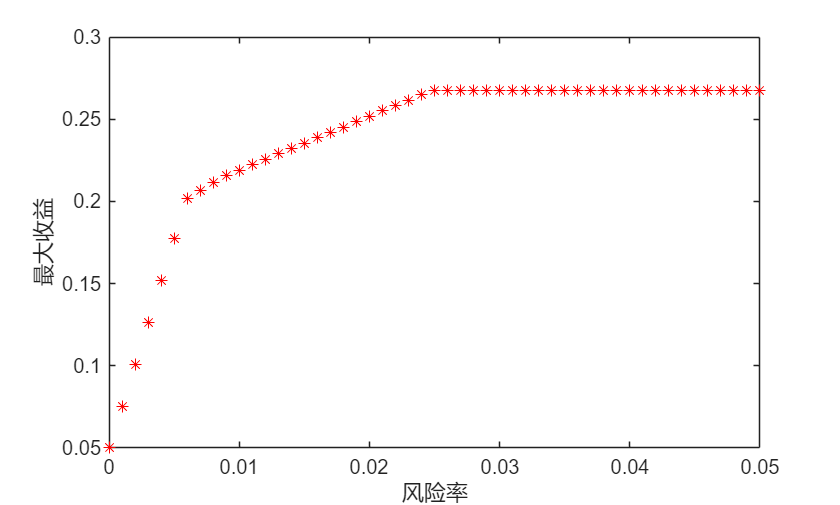

plot(a,Q,'*r')
xlabel('风险率')
ylabel('最大收益')